% 问题：假设您有一家健康诊所的数据。您想要设计一个网络，
% 该网络可以基于 13 个解剖学测量值（X）来预测人的体脂率（Y)。
% 您总共有 252 个人的样本，其中包括这 13 项数据和相关的体脂率。
clear

## 加载数据

脚本假设输入向量和目标向量已加载到工作区中。 如果未加载数据，可以按如下方式加载它们：

load bodyfat_dataset
inputs = bodyfatInputs;
targets = bodyfatTargets;
% 此数据集是工具箱的示例数据集之一（请参阅浅层神经网络的样本数据集）。
% 您可以输入命令 help nndatasets 来查看所有可用数据集的列表
% 。load 命令还允许您使用自己的变量名称从这些数据集中的任何一个加载变量。例如，命令
% [inputs,targets] = bodyfat_dataset;
% 会将体脂输入加载到数组 inputs 中，将体脂目标加载到数组 targets 中。

## 创建网络

创建一个网络。用于函数拟合（或回归）问题的默认网络 fitnet 是一个前馈网络， 其默认 tan-sigmoid 传递函数在隐藏层，线性传递函数在输出层。 首先，您（人为地选择）将十个神经元分配给一个隐藏层。 网络有一个输出神经元，因为只有一个目标值与每个输入向量关联。

hiddenLayerSize = 10;
net = fitnet(hiddenLayerSize);
% 注意
% 
% 神经元越多，需要的计算也越多；
% 当数量设置得太高时，可能会出现数据过拟合倾向，但这使网络能够求解更复杂的问题。
% 层越多，需要的计算也越多，但使用更多的层可以使网络更高效地求解复杂问题。
% 要使用多个隐藏层，请在 fitnet 命令中输入隐藏层大小作为数组的元素。
% 设置数据划分。

net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
% 基于以上设置，输入向量和目标向量都将被随机划分为三组，其中 70% 用于训练，15% 用于验证，15% 用于测试。（有关数据划分流程的更多讨论，请参阅划分数据。）
% 
% 训练网络。网络使用默认的 Levenberg-Marquardt 算法 (trainlm) 进行训练。
% 对于 Levenberg-Marquardt 无法产生期望的准确结果的问题，或对于大型数据问题，
% 请考虑使用以下命令之一将网络训练函数设置为贝叶斯正则化（trainbr）或量化共轭梯度（trainscg）：

net.trainFcn = 'trainbr';
% net.trainFcn = 'trainscg';

## 训练网络

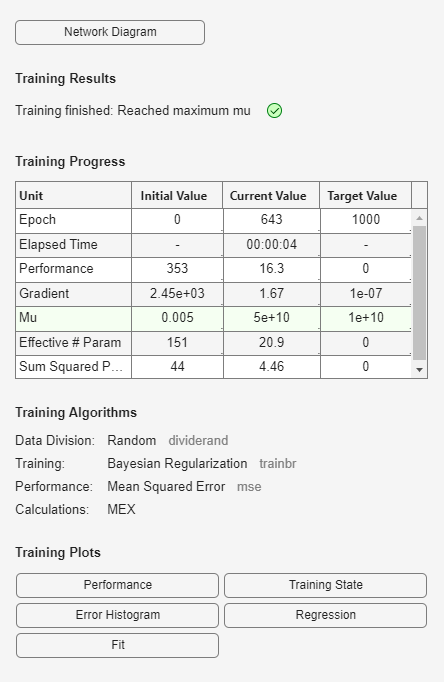

[net, tr] = train(net, inputs, targets);

% 在训练期间，将打开以下训练窗口。此窗口显示训练进度，并允许您随时点击 Stop Training 来中断训练。
% 当验证误差在六次迭代中持续增加时，训练停止，即在第 20 次迭代时停止。
% 如果在训练窗口中点击 Performance，将显示表示训练误差、验证误差和测试误差的图，
% 如下图所示。在此示例中，结果是合理的，原因如下：
% 最终均方误差很小。
% 测试集误差和验证集误差具有相似特性。
% 在第 14 次迭代（出现最佳验证性能）前未出现明显的过拟合。

## 测试网络。

您可以使用经过训练的网络来计算网络输出。以下代码将计算网络输出、误差和整体性能。

outputs = net(inputs);
errors = gsubtract(targets, outputs); % 两个矩阵相减
performance = perform(net, targets, outputs)

performance = 16.7353

% performance =  19.3193

% 通过使用训练记录中的测试索引，还可以只针对测试集计算网络性能。
% （有关训练记录的完整说明，请参阅分析训练后的浅层神经网络性能。）

tInd = tr.testInd;
tstOutputs = net(inputs(:, tInd));
tstPerform = perform(net, targets(tInd), tstOutputs)

tstPerform = 19.1728

% tstPerform =   53.7680

% 对网络响应进行一些分析。如果在训练窗口中点击 Regression，则可以在网络输出和相应目标之间执行线性回归。

% 对于训练、测试和验证，输出非常好地跟踪了目标，并且总响应的 R 值超过 0.96。
% 如果需要更准确的结果，可以尝试以下任一方法：
% 使用 init 将初始网络权重和偏差重置为新值，然后再次训练（请参阅初始化权重 (init)）。
% 增加隐藏神经元的数量。
% 增加训练向量的数量。
% 增加输入值的数量（如果有更多相关信息可用）。
% 尝试其他训练算法（请参阅训练算法）。
% 在此例中，网络响应是令人满意的，现在您可以将该网络用于新输入。

## 查看网络图。

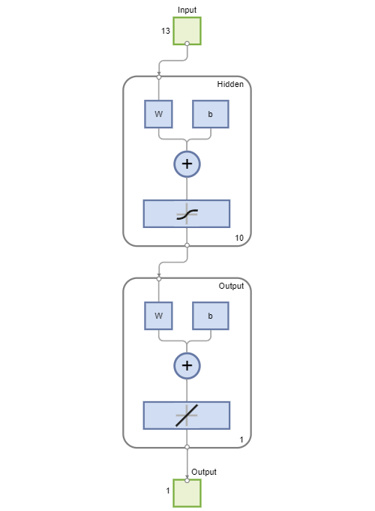

view(net)


% 要进一步熟悉命令行操作，请尝试以下任务：
% 在训练期间，打开绘图窗口（如回归图），并观察其动画效果。
% 从命令行使用 plotfit、plotregression、plottrainstate 和 plotperform 等函数绘图。
% （有关使用这些函数的详细信息，请参阅其参考页。）
% 此外，从命令行进行训练时，可以查看高级脚本以了解更多选项。
% 每次训练神经网络时，由于初始权重和偏置值不同，并且将数据划分为训练集、
% 验证集和测试集的方式也不同，可能会产生不同的解。
% 因此，针对同一问题训练的不同神经网络对同一输入可能给出不同输出。
% 为确保找到准确度良好的神经网络，需要多次重新训练。
% 如果需要更高的准确度，可以采用几种其他方法来改进初始解。
% 有关详细信息，请参阅提高浅层神经网络泛化能力，避免过拟合。